% SIMULERING AF SYSTEM
% 7 mikrofoner får et input a 1, 3, 10 kHz
% deres input er justeret efter position i array
% 3 ULAer med 3 mikrofoninput i hver 
% DAS på hver ULA - kræver fractional delay
% Frekvensfiltrering før eller efter DAS??
% Sum outputs
% PSD

clc
clear
close all
% Change DAS parameters in DAS.mlx
load('DASParams.mat')

fs = 48e3;
t = 0:1/fs:1;
inputAng = 100

inputAng = 100

steerAng

steerAng = 138.0100

c = 1496;
micTimeOffsets = micArray.*cosd(inputAng)/c

micTimeOffsets = 1.0e-03 *

         0   -0.0435   -0.0532   -0.0580   -0.0629   -0.0725   -0.1161


 % inputSig = sin(2*pi*(t+micTimeOffsets')*1000) ...
 %     + sin(2*pi*(t+micTimeOffsets')*3000) ...
 %     + sin(2*pi*(t+micTimeOffsets')*10000);
%inputSig = sin(2*pi*(t+micTimeOffsets').*linspace(1,24e3,length(t)))
inputSig = sin(2*pi*(t+micTimeOffsets').*randi(24e3,1,length(t)))

inputSig =          0    0.7863    0.9436    0.8537   -0.9977    0.9980    0.9374   -0.6295    0.8591   -0.9953   -0.1564   -0.5058    0.2548   -0.9377    0.0996   -0.0589   -0.0565   -0.4448    0.9736   -0.2194   -0.9983    0.1066    0.5789    0.1598   -0.7604    0.2398    0.0474   -0.8581    0.1549   -0.2359    0.8422    0.8554    0.8488    0.9992   -0.6040   -0.2531    0.9716   -0.2813   -0.6674   -0.0031    0.9973   -0.3735   -0.8002    0.7624   -0.2156   -0.6874   -0.4911    0.3475   -0.8409    0.6453
   -0.5252   -0.8336   -0.0551    0.7979    0.7566    0.8142    0.9508   -0.8768    0.6916    0.5862    0.9627   -0.5695    0.2112   -0.3728    0.6537    0.1060    0.3137    0.3444   -0.9700   -0.9138    0.3272   -0.9974   -0.5930    0.6502   -0.8769    0.6660    0.3422    0.2389    0.7494    0.9994   -0.5417   -0.8369    1.0000    0.4978   -0.6366   -0.8365   -1.0000    0.9857   -0.9561   -0.8996    0.7704    0.1424   -0.4010   -0.9667   -0.6282   -0.6697    0.4686   -0.1286   -0.82

zeroPad = 100;
%inputSig = [zeros(7,zeroPad) inputSig zeros(7,zeroPad)];


% Time offset in samples
tauOffset1 = tauULA1*fs; % Mic 1, 4, 7
tauOffset2 = tauULA2*fs; % Mic 2, 4, 6
tauOffset3 = tauULA3*fs; % Mic 3, 4, 5

% Fractional delays TBI

cfULA1 = 1700;
cfULA2 = [cfULA1 4000];
cfULA3 = cfULA2(2);

FIRULA1 = makeFIR(cfULA1, 100, fs, 'low');
FIRULA2 = makeFIR(cfULA2, 100, fs, 'bandpass');
FIRULA3 = makeFIR(cfULA3, 100, fs, 'high');
% freqz(FIRULA1,1,1024,fs);
% hold on
% freqz(FIRULA2,1,1024,fs);
% freqz(FIRULA3,1,1024,fs);
% hold off


%for inputang
    %for freq

% Filter inputs 
inputSigULA1 = filter(FIRULA1,1,inputSig,[],2);
inputSigULA1 = [zeros(7,zeroPad) inputSigULA1 zeros(7,zeroPad)];
inputSigULA2 = filter(FIRULA2,1,inputSig,[],2);
inputSigULA2 = [zeros(7,zeroPad) inputSigULA2 zeros(7,zeroPad)];
inputSigULA3 = filter(FIRULA3,1,inputSig,[],2);
inputSigULA3 = [zeros(7,zeroPad) inputSigULA3 zeros(7,zeroPad)];

% Output of each ULA
% hmm måske noget indeksfejl
ULA1Sum = inputSigULA1(1,zeroPad+round(tauOffset1(1)):end-1-zeroPad-round(tauOffset1(1)))...
    + inputSigULA1(4,zeroPad+round(tauOffset1(2)):end-1-zeroPad+round(tauOffset1(2))) ...
    + inputSigULA1(7,zeroPad+round(tauOffset1(3)):end-1-zeroPad+round(tauOffset1(3)));
ULA1Sum = ULA1Sum * 1/3;

ULA2Sum = inputSigULA2(2,zeroPad+round(tauOffset2(1)):end-1-zeroPad-round(tauOffset2(1)))...
    + inputSigULA2(4,zeroPad+round(tauOffset2(2)):end-1-zeroPad+round(tauOffset2(2))) ...
    + inputSigULA2(6,zeroPad+round(tauOffset2(3)):end-1-zeroPad+round(tauOffset2(3)));
ULA2Sum = ULA2Sum * 1/3;

ULA3Sum = inputSigULA3(3,zeroPad+round(tauOffset3(1)):end-1-zeroPad-round(tauOffset3(1)))...
    + inputSigULA3(4,zeroPad+round(tauOffset3(2)):end-1-zeroPad+round(tauOffset3(2))) ...
    + inputSigULA3(5,zeroPad+round(tauOffset3(3)):end-1-zeroPad+round(tauOffset3(3)));
ULA3Sum = ULA3Sum * 1/3;

arrayOutput = (ULA1Sum + ULA2Sum + ULA3Sum)%*1/3

arrayOutput =    -0.0025   -0.0023   -0.0018   -0.0012   -0.0004    0.0005    0.0020    0.0030    0.0038    0.0041    0.0049    0.0051    0.0056    0.0057    0.0057    0.0054    0.0043    0.0019   -0.0012   -0.0051   -0.0104   -0.0157   -0.0220   -0.0292   -0.0370   -0.0457   -0.0552   -0.0652   -0.0751   -0.0830   -0.0873   -0.0864   -0.0801   -0.0668   -0.0489   -0.0301   -0.0139   -0.0051   -0.0061   -0.0197   -0.0440   -0.0741   -0.1035   -0.1235   -0.1276   -0.1103   -0.0716   -0.0158    0.0473   -0.1333


%arrayOutput = (ULA1Sum + ULA3Sum)%*1/3
rms(arrayOutput)

ans = 0.3599

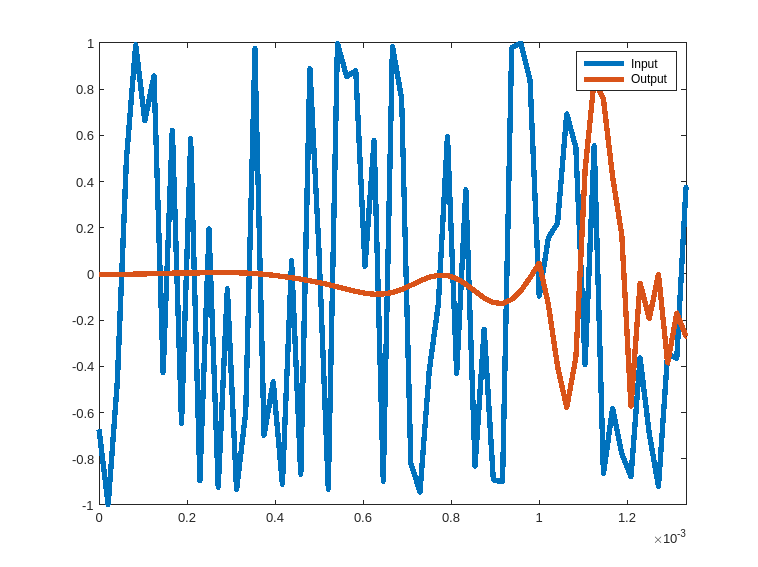


% plot(t, inputSig(4,:), 'LineWidth', 4)
% hold on
% plot(t, arrayOutput, 'LineWidth', 4)
% %plot(t(1:end-70),arrayOutput(71:end), 'LineWidth', 4)
% xlim([0 20/15000])
% legend('Input', 'Output')
% hold off

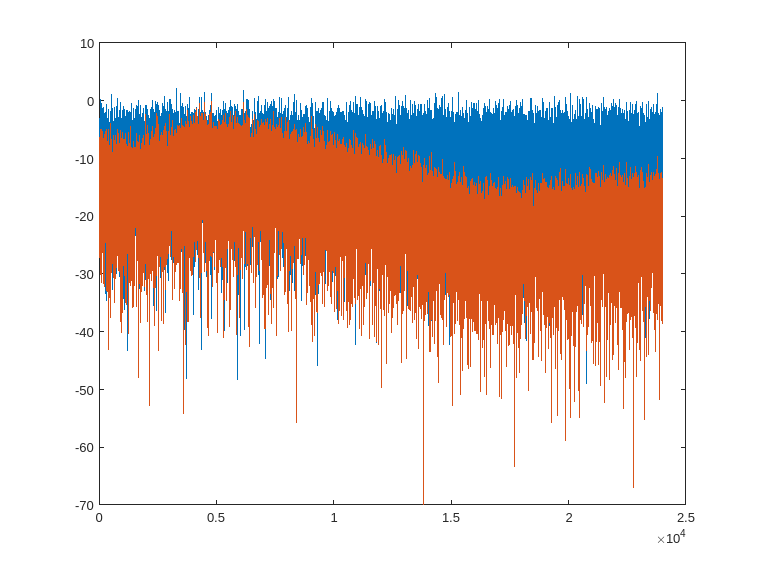


% [powerInputFilt,omegaInputFilt] = periodogram((inputSigULA1(4,zeroPad:end-zeroPad)+inputSigULA2(4,zeroPad:end-zeroPad)+inputSigULA3(4,zeroPad:end-zeroPad))/3);
% plot(omegaInputFilt*fs/(2*pi),10*log10(powerInputFilt))



%
% [powerInput,omegaInput] = periodogram(inputSig(4,:),[],4096,fs);
% plot(omegaInput,10*log10(powerInput))
% hold on
% 
% [powerOutput,omegaOutput] = periodogram(arrayOutput,[],4096,fs);
% plot(omegaOutput,10*log10(powerOutput))

% [powerULA1,omegaULA1] = periodogram(ULA1Sum);
% plot(omegaULA1*fs/(2*pi),10*log10(powerULA1))
% 
% [powerULA2,omegaULA2] = periodogram(ULA2Sum);
% plot(omegaULA2*fs/(2*pi),10*log10(powerULA2))
% 
% [powerULA3,omegaULA3] = periodogram(ULA3Sum);
% plot(omegaULA3*fs/(2*pi),10*log10(powerULA3))
% legend('Input', 'Combined Output', 'ULA1', 'ULA2', 'ULA3')
%hold off



% pwelch(inputSig(4,:))
% hold on
% pwelch(arrayOutput)
% hold off
% 
% stft(inputSig(4,:),fs,OverlapLength=98,FFTLength=128);


function coeffs_adjusted = makeFIR(Fc, order, fs, type)
if ~exist('type', 'var') 
    coeffs = fir1(order,2*Fc/fs);
else 
    coeffs = fir1(order,2*Fc/fs, type);
end 
[mag, freq] = freqz(coeffs,1,1024,fs);
magdB = 20*log10(abs(mag));
if length(Fc) == 1
    [~, minIndex] = min(abs(magdB + 3));
    Fc_3dB = freq(minIndex);
    Fc_adjusted = Fc * (Fc/Fc_3dB);
    coeffs_adjusted = fir1(order, 2*Fc_adjusted/fs, type);
elseif length(Fc) == 2
    %[~, minIndexLow] = min(abs(magdB + 3));
    minIndexLow = find(abs(magdB)<3,1);
    minIndexHigh = find(abs(magdB(minIndexLow:end))>3,1) + minIndexLow;
    FcLow_3dB = freq(minIndexLow);
    FcHigh_3dB = freq(minIndexHigh);
    FcLow_adjusted = Fc(1) * (Fc(1)/FcLow_3dB);
    FcHigh_adjusted = Fc(2) * (Fc(2)/FcHigh_3dB);
    coeffs_adjusted = fir1(order, 2*[FcLow_adjusted FcHigh_adjusted]/fs, type);
else
    disp("nederen")
end
end